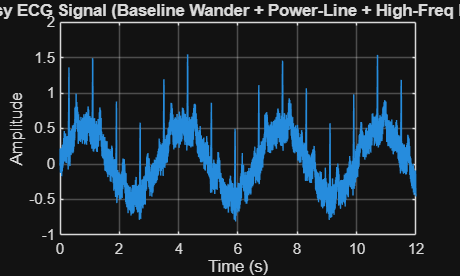

clear; clc; close all;
%% 1) GET ECG SIGNAL
% Generate a synthetic noisy ECG ----
% We build one heartbeat (P-QRS-T complex) ourselves as a sum of
% Gaussian pulses -- no toolbox-specific functions required, so this
% works on any MATLAB install -- then repeat it for multiple beats
% and add realistic noise so we have a controlled signal to clean.
Fs = 500;                       % Sampling frequency (Hz)
% --- Build one synthetic heartbeat (P-QRS-T) as a sum of Gaussian
%     pulses -- no toolbox-specific function or local function needed.
beatDuration = 0.8;                      % seconds per heartbeat
tb = 0 : 1/Fs : beatDuration - 1/Fs;
% Each wave: [amplitude, center time (s), width (s)]
P = [0.15,  0.15, 0.020];
Q = [-0.15, 0.28, 0.008];
R = [1.00,  0.30, 0.008];
S = [-0.25, 0.32, 0.008];
T = [0.30,  0.55, 0.040];
gaussWave = @(x, w) w(1) * exp(-((x - w(2)).^2) / (2*w(3)^2));
beat = gaussWave(tb, P) + gaussWave(tb, Q) + gaussWave(tb, R) + ...
       gaussWave(tb, S) + gaussWave(tb, T);
numBeats = 15;
ecg_clean_ref = repmat(beat, 1, numBeats);   % concatenate beats
N = length(ecg_clean_ref);
t = (0:N-1) / Fs;
% --- Add baseline wander (slow drift, <1 Hz) ---
baselineWander = 0.5 * sin(2*pi*0.3*t);
% --- Add power-line interference (50 Hz) ---
powerlineNoise = 0.15 * sin(2*pi*50*t);
% --- Add high-frequency noise (random) ---
highFreqNoise = 0.05 * randn(1, N);
ecg_noisy = ecg_clean_ref + baselineWander + powerlineNoise + highFreqNoise;
figure;
plot(t, ecg_noisy);
xlabel('Time (s)'); ylabel('Amplitude');
title('Noisy ECG Signal (Baseline Wander + Power-Line + High-Freq Noise)');
grid on;

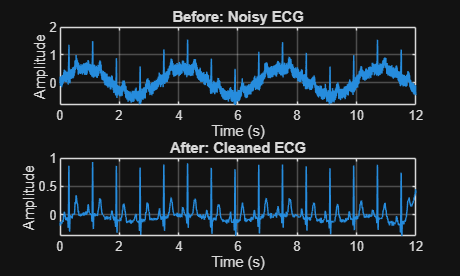


%% 2) REMOVE BASELINE WANDER (high-pass filter, cutoff ~0.5 Hz)
Fc_hp = 0.5;                              % cutoff frequency (Hz)
[b_hp, a_hp] = butter(2, Fc_hp/(Fs/2), 'high');
ecg_no_baseline = filtfilt(b_hp, a_hp, ecg_noisy);

%% 3) REMOVE POWER-LINE INTERFERENCE (notch filter at 50 Hz)
Fnotch = 50;                              % power-line frequency (Hz)
Wo = Fnotch/(Fs/2);
BW = Wo/35;                               % narrow notch bandwidth
[b_notch, a_notch] = iirnotch(Wo, BW);
ecg_no_powerline = filtfilt(b_notch, a_notch, ecg_no_baseline);

%% 4) REMOVE HIGH-FREQUENCY NOISE (low-pass filter, cutoff ~40 Hz)
Fc_lp = 40;                               % cutoff frequency (Hz)
[b_lp, a_lp] = butter(4, Fc_lp/(Fs/2), 'low');
ecg_cleaned = filtfilt(b_lp, a_lp, ecg_no_powerline);

%% 5) COMPARE BEFORE / AFTER
figure;
subplot(2,1,1);
plot(t, ecg_noisy);
xlabel('Time (s)'); ylabel('Amplitude');
title('Before: Noisy ECG');
grid on;
subplot(2,1,2);
plot(t, ecg_cleaned);
xlabel('Time (s)'); ylabel('Amplitude');
title('After: Cleaned ECG');
grid on;

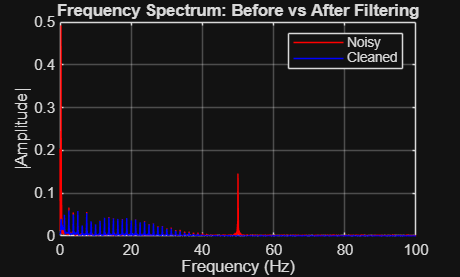


%% 6) FREQUENCY SPECTRUM COMPARISON (see noise components removed)
NFFT = 2^nextpow2(N);
f = Fs/2 * linspace(0, 1, NFFT/2+1);
Y_noisy = fft(ecg_noisy, NFFT) / N;
Y_clean = fft(ecg_cleaned, NFFT) / N;
figure;
plot(f, 2*abs(Y_noisy(1:NFFT/2+1)), 'r'); hold on;
plot(f, 2*abs(Y_clean(1:NFFT/2+1)), 'b');
xlabel('Frequency (Hz)'); ylabel('|Amplitude|');
title('Frequency Spectrum: Before vs After Filtering');
legend('Noisy', 'Cleaned');
xlim([0 100]);
grid on;

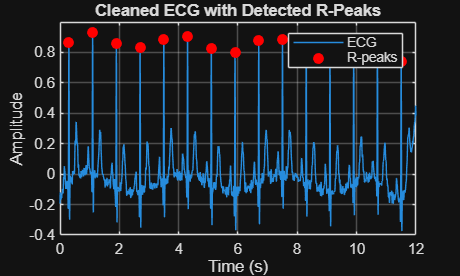


%% 7) R-PEAK DETECTION
% R-peaks are the tall sharp spikes in each heartbeat. We use findpeaks
% with a minimum height and minimum spacing to avoid detecting smaller
% P/T waves or noise as false R-peaks.
minPeakHeight = 0.5 * max(ecg_cleaned);     % adaptive threshold
minPeakDistance = round(0.3 * Fs);          % min 0.3s between beats (~200 bpm max)
[peakVals, peakLocs] = findpeaks(ecg_cleaned, ...
    'MinPeakHeight', minPeakHeight, ...
    'MinPeakDistance', minPeakDistance);
peakTimes = peakLocs / Fs;
figure;
plot(t, ecg_cleaned); hold on;
plot(peakTimes, peakVals, 'ro', 'MarkerFaceColor', 'r');
xlabel('Time (s)'); ylabel('Amplitude');
title('Cleaned ECG with Detected R-Peaks');
legend('ECG', 'R-peaks');
grid on;


%% 8) CALCULATE HEART RATE
RR_intervals = diff(peakTimes);             % time between consecutive R-peaks (s)
avgRR = mean(RR_intervals);                 % average R-R interval (s)
heartRate = 60 / avgRR;                     % beats per minute
fprintf('Number of R-peaks detected: %d\n', length(peakLocs));

Number of R-peaks detected: 15


fprintf('Average R-R interval: %.3f s\n', avgRR);

Average R-R interval: 0.800 s


fprintf('Estimated Heart Rate: %.1f BPM\n', heartRate);

Estimated Heart Rate: 75.0 BPM


%% ================================================================
%  DONE
% ================================================================
disp('ECG noise removal and heart rate estimation complete.');

ECG noise removal and heart rate estimation complete.
